# Project 2.1

## (a) Plot sol for Dirichlet BC

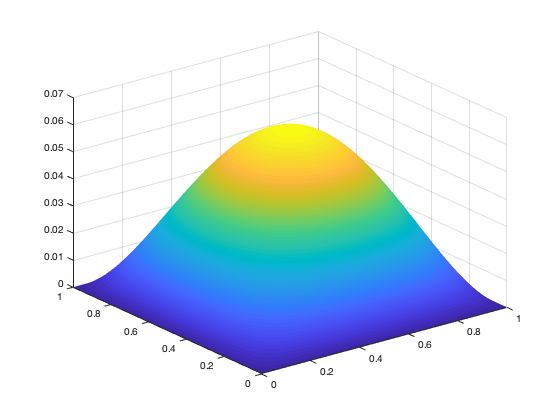

omega = linspace(0,1,1e3);
[MX,MY] = meshgrid(omega,omega);
U = exact_2D(MX,MY,'Problem 2.1 DBC ');
surf(MX,MY,U,'EdgeColor','None')

Mesh 1

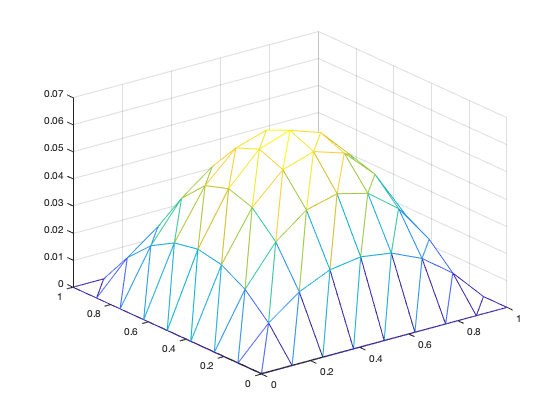

figure()
Global2D();

Mesh 2

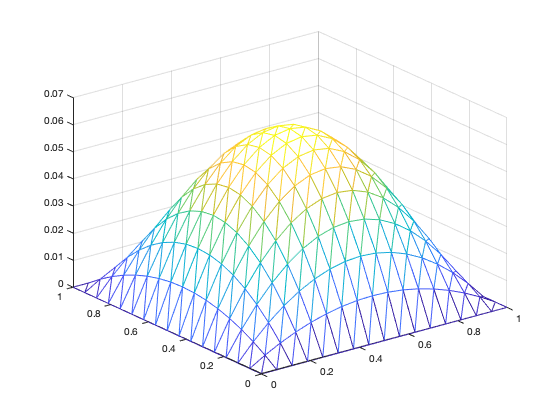

figure()
Global2D();

Mesh 3

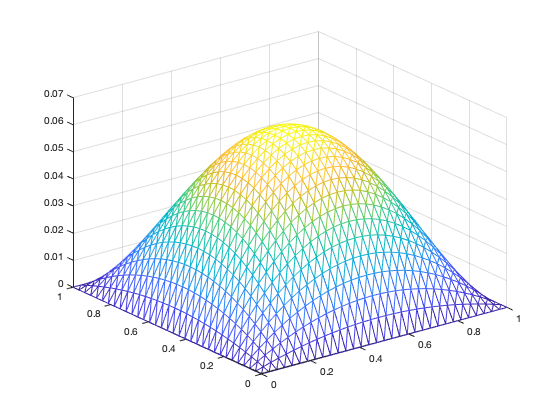

figure()
Global2D();

## (b) Compute $L^2$ and $L^{\infty}$ error 

Mesh 1

L2 = zeros(3,1);
Linf = zeros(3,1);
[L2(1),Linf(1),~] = error2D();

L2 =     0.0015454            0            0


Linf =     0.0022489            0            0


Mesh 2

[L2(2),Linf(2),~] = error2D();

L2 =     0.0015454   0.00039272            0


Linf =     0.0022489   0.00056849            0


Mesh 3

[L2(3),Linf(3),~] = error2D();

L2 =     0.0015454   0.00039272   9.8582e-05


Linf =     0.0022489   0.00056849   0.00014263


table(["Mesh 1";"Mesh 2";"Mesh 3";"Unstructured"],L2,Linf)

## (c) Rate of convergence

L2factor = [NaN;L2(1:2)./L2(2:3)];
Linffactor = [NaN;Linf(1:2)./Linf(2:3)];
L2rate = L2factor/2;
Linfrate = Linffactor/2;
table(L2,L2factor,L2rate,Linf,Linffactor,Linfrate)

ans = 3×6 table
        L2        L2factor    L2rate       Linf       Linffactor    Linfrate
    __________    ________    ______    __________    __________    ________
     0.0015454        NaN        NaN     0.0022489         NaN          NaN 
    0.00039272     3.9352     1.9676    0.00056849      3.9559       1.9779 
    9.8582e-05     3.9837     1.9919    0.00014263      3.9858       1.9929 

Each refinement of mesh has caused both errors to decrease by a factor of ~4, because x and y are halved for each refinement. The convergence rate is approaching 2, which is the theoretical value of convergence rate.

## (d) Plot log error versus log spacing

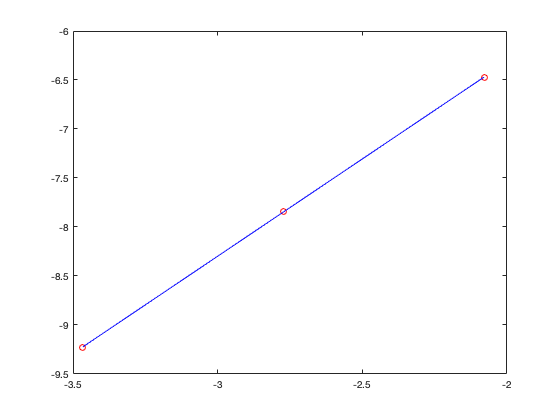

h = [1/8;1/16;1/32]; %spacing for meshes

figure()
plot(log(h),log(L2),'ro')
hold on 
coeffL2 = polyfit(log(h),log(L2),1);
plot(log(h),polyval(coeffL2,log(h)),'b')

slopeL2 = coeffL2(1)

slopeL2 =        1.9853

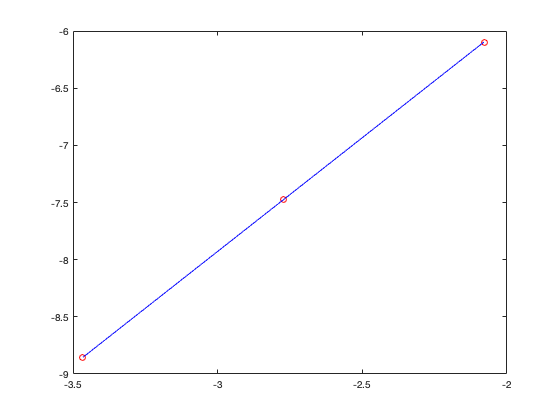



figure()
plot(log(h),log(Linf),'ro')
hold on 
coeffLinf = polyfit(log(h),log(Linf),1);
plot(log(h),polyval(coeffLinf,log(h)),'b')

slopeLinf = coeffLinf(1)

slopeLinf =        1.9894

The 'average' rate of convergence for $L_2$ error is 1.9853.

The 'average' rate of convergence for $L_{\infty}$ error is 1.9894.

## (e) Plots for mixed BC

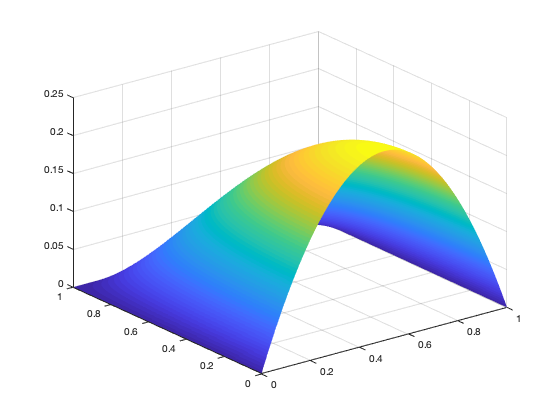

figure()
U = exact_2D(MX,MY,'Problem 2.1 MBC ');
surf(MX,MY,U,'EdgeColor','None')

 Structured Mesh

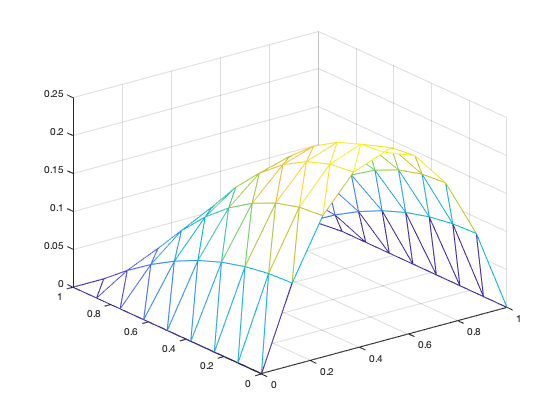

figure()
Global2D();

Unstructured Mesh

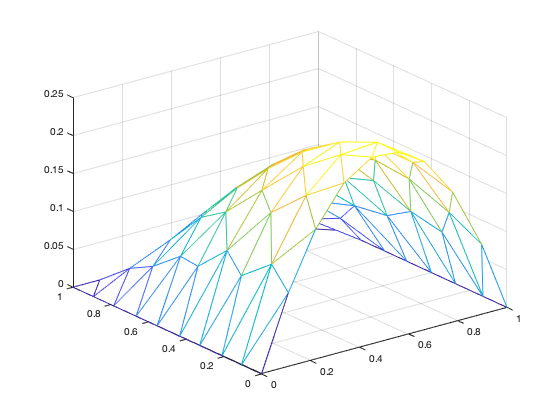

figure()
Global2D();

## (f) $L_2$ and $L_{\infty}$ norm and comparsion

ML2 = zeros(2,1);
MLinf = zeros(2,1);

Structured Mesh

[ML2(1),MLinf(1),~] = error2D();

ML2 =     0.0031458            0


MLinf =     0.0043137            0


Unstructured Mesh

[ML2(2),MLinf(2),~] = error2D();

ML2 =     0.0031458    0.0025783


MLinf =     0.0043137    0.0042669


table(["Structured Mesh";"Unstructured Mesh"],ML2,MLinf)

Both $L_2$ and $L_{\infty}$ in structured mesh are smaller than these in unstructured mesh.

I expect the unstrcutured mesh will give better result. Because the unstructured mesh is more flexible and is created to fit the solution better than a structured mesh. So it is supposed to give a more accurate solution than the structured mesh.